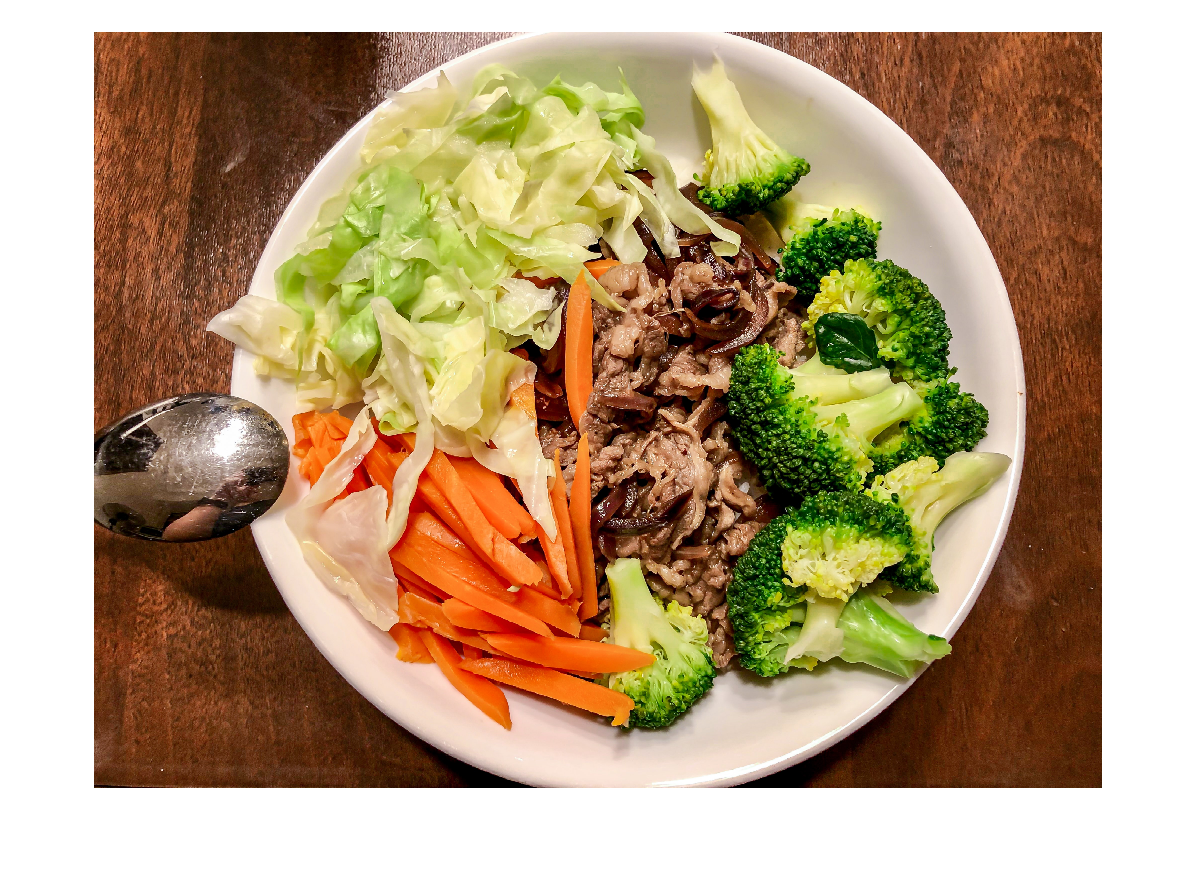

%%Project food classification main LiveScript
%%This will contain the actual code we will use
%%Martin Iversen 
%%Last revision: 08.05.2021

%%Reads the image
image = imread('images/hard/Test26.jpg');

%%Shows original image
imshow(image)

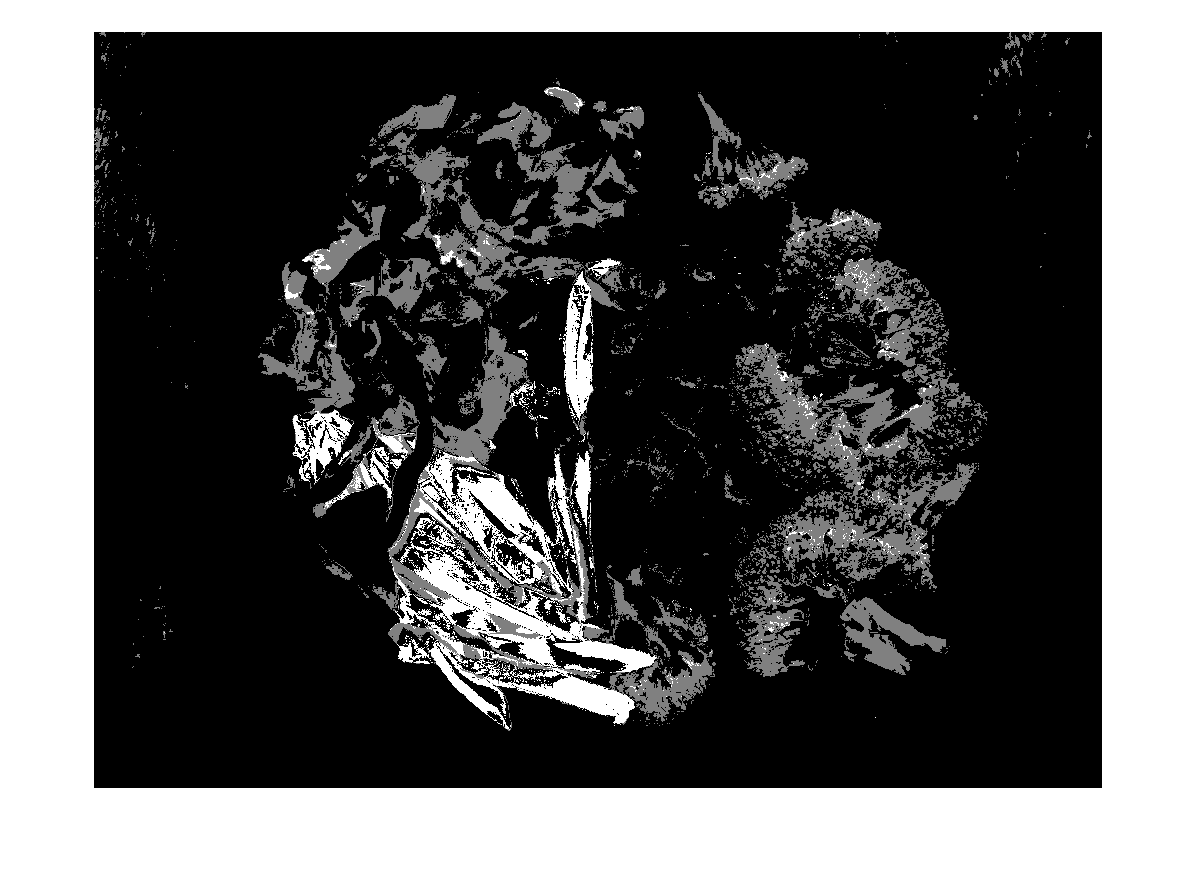


%%Runs the different color functions for the image 
green = Green(image);        
lightGreen = LightGreen(image);
red = MoreRed(image);
yellow = Yellow(image);
purple = Purple(image);
orange = Orange(image);

%%Fuses both green masks to cover as much green as possible
greenResult = imfuse(lightGreen,green,'blend');

%%Fuses all of the masks together with diff method
result = imfuse(greenResult, red,'diff');
result = imfuse(yellow,result,'diff');
result = imfuse(purple,result,'diff');
result = imfuse(orange, result,'diff');

%%Shows resulting image pre post-processing
imshow(result)

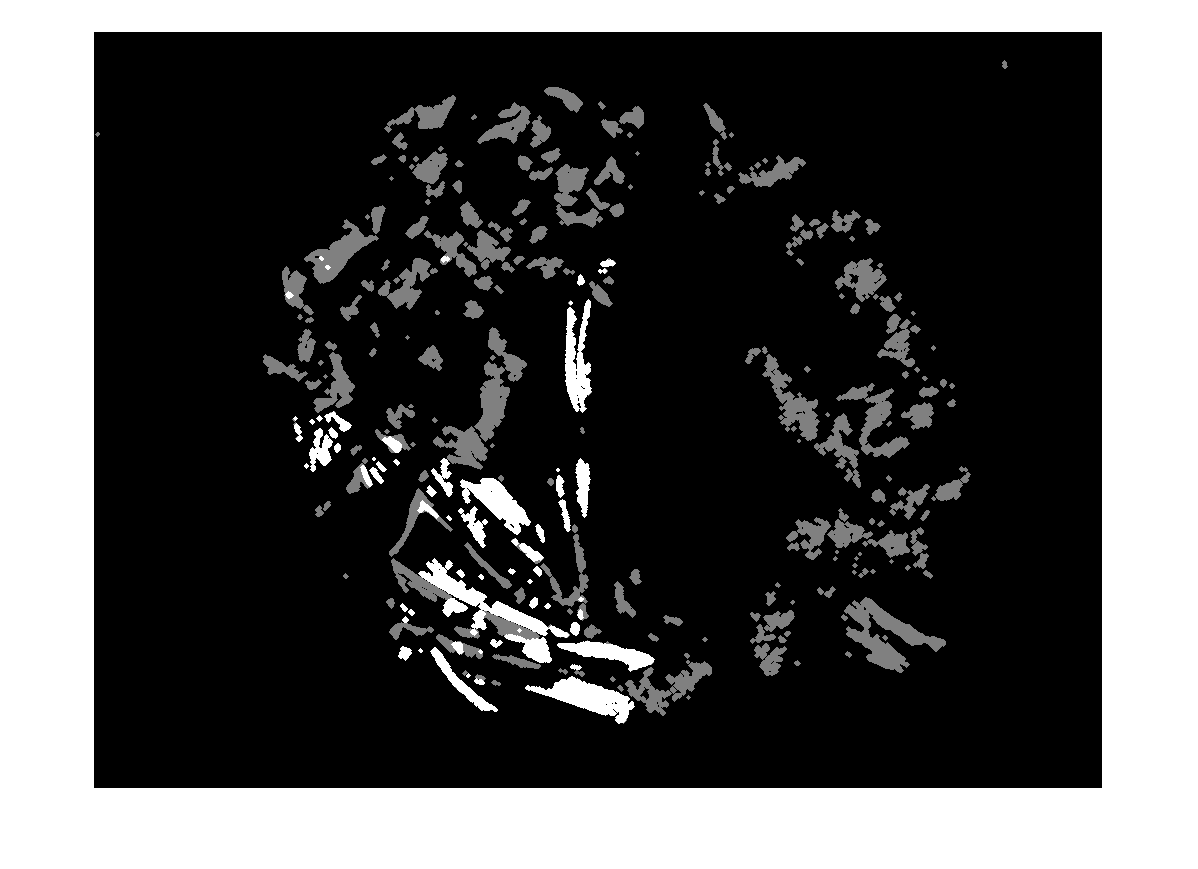


%%Defines a morphological structuring object with size 5
rough = strel('diamond',5);

%%Perform morphological opening on the image
roughProcessed = imopen(result,rough);
imshow(roughProcessed)

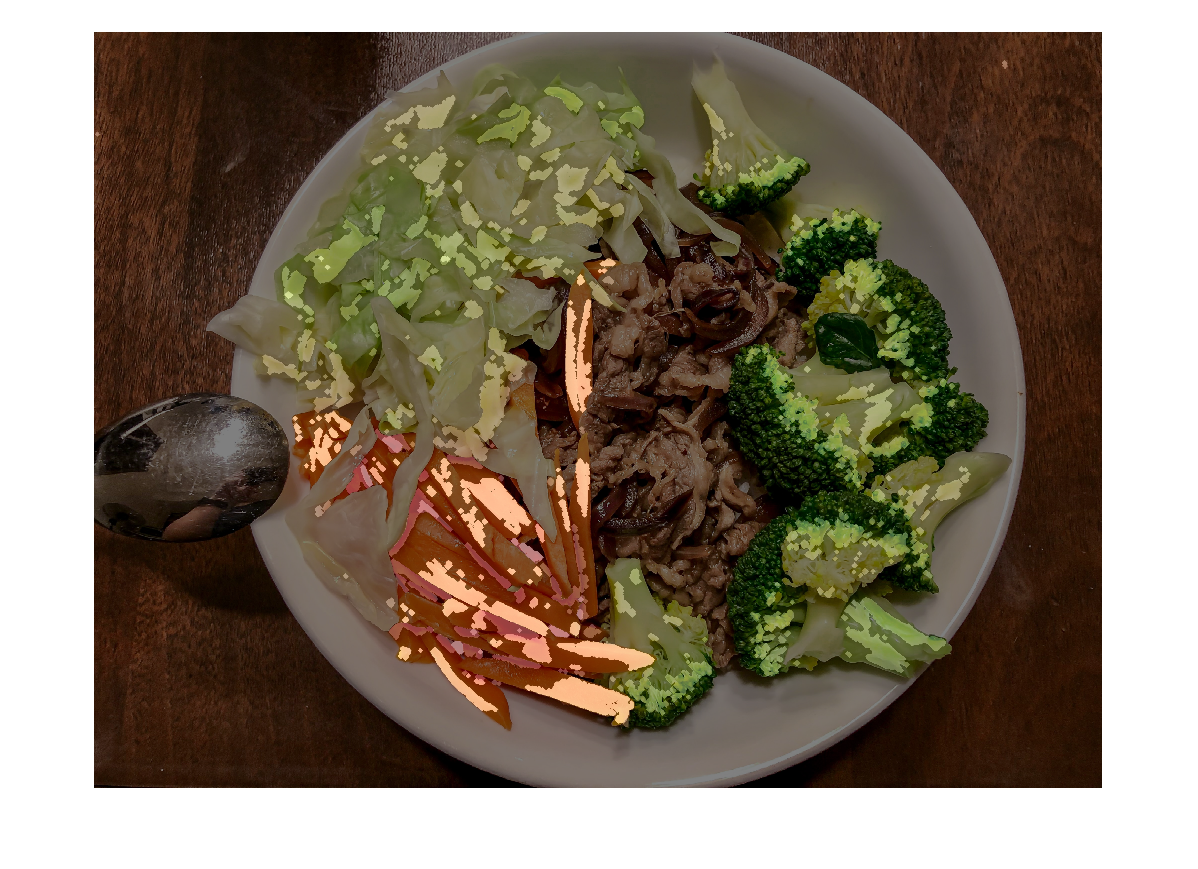


fused = imfuse(image,roughProcessed,'blend');

%%Display the result
imshow(fused)